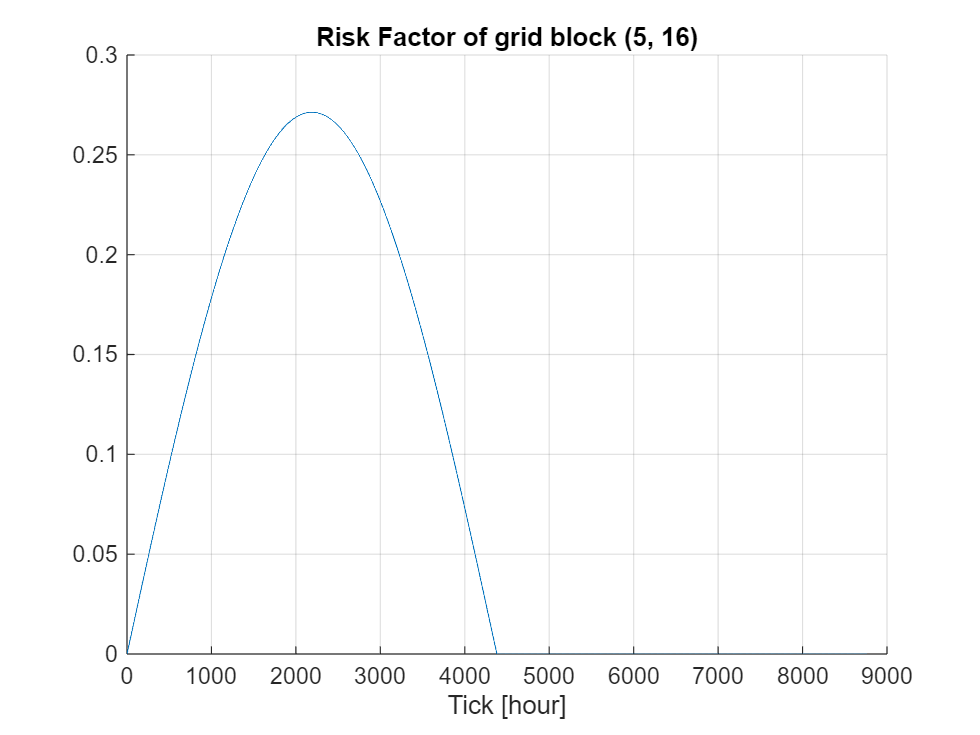


%#ok<*CLALL>

clear all;clc 

% Let 1 tick be 1 hour. 
gridSettings = gridSettingsClass; 
gridSettings.gridSize = [128, 256]; 
gridSettings.ticksPerYear = 365*24; 
gridSettings.restoreGridHealthRate = 1/gridSettings.ticksPerYear; 
gridSettings.restoreGridHealthCost = 1; 
gridSettings.newFireIntensityMax = 1E-1; 
gridSettings.newFireIntensityMean = 1; 
gridSettings.newFireIntensityStandardDeviation = 0.1; 
gridSettings.peakIntensityHealth_mean = 0.6; 
gridSettings.peakIntensityHealth_standardDeviation = 0.02; 

simGrid = gridClass(gridSettings); 

% Take a peek at the risk factor of a grid block (5, 16): 
tspan = 1 : 365*24; 
riskFactorPeekaboo = zeros(length(tspan), 1); 
tic; 
for tick = tspan
    simGrid.updateRiskFactor(tick); 
    riskFactorPeekaboo(tick) = simGrid.riskFactor(5, 16); 
end
clf; 
hold on; 
grid on; 
plot(tspan, riskFactorPeekaboo); 
xlabel("Tick [hour]"); 
title("Risk Factor of grid block (5, 16)"); 
hold off; 

toc; 

Elapsed time is 0.659751 seconds.
